## Download Data 

userpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "src"))
download_from_sciebo('https://uni-bonn.sciebo.de/s/YT3iaH9Po0LJMxR', 'data/steinmetz_2017-12-05_Lederberg.nc')
addpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "data"))

ff = netcdf.NetCDF("data/steinmetz_2017-12-05_Lederberg.nc")

ff =   NetCDF with properties:

     filename: "data/steinmetz_2017-12-05_Lederberg.nc"
    variables: {1×31 cell}



spike_counts_ = ff.read2table("spike_count")

spike_counts = 59330000×4 table
    time    trial    cell    spike_count
    ____    _____    ____    ___________

    0.01      1       1           0     
    0.02      1       1           1     
    0.03      1       1           0     
    0.04      1       1           0     
    0.05      1       1           0     
    0.06      1       1           0     
    0.07      1       1           0     
    0.08      1       1           0     
    0.09      1       1           0     
     0.1      1       1           1     
    0.11      1       1           0     
    0.12      1       1           0     
    0.13      1       1           0     
    0.14      1       1           0     
    0.15      1       1           0     
    0.16      1       1           0     


## Convert Spiking events into Spike Counts

%data = readtable('data/steinmetz_2017-01-08_Muller_spikes.csv')

data = 1836009×4 table
    spike_id    spike_time    spike_cell    spike_trial
    ________    __________    __________    ___________

        1         2.3629          1              1     
        2         2.3849          1              1     
        3         1.4507          1              2     
        4         1.4596          1              2     
        5         1.9635          1              2     
        6         1.9653          1              2     
        7         1.9708          1              2     
        8         1.9727          1              2     
        9         1.9751          1              2     
       10         1.9776          1              2     
       11         1.5432          1              6     
       12         1.5456          1              6     
       13         1.5476          1              6     


%ncdisp("data/steinmetz_2017-12-05_Lederberg.nc")

spike_counts = ncread("data/steinmetz_2017-12-05_Lederberg.nc","spike_count") ;


%spike_counts = reshape(spike_counts, 698, 340, 250)

 brain_areas = ncread("data/steinmetz_2017-12-05_Lederberg.nc","brain_groups") ;

 brain_areas(brain_areas =='visual cortex')

ans = 145×1 string array
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"
    "visual cortex"



 mask = find(brain_areas=="visual cortex")

mask =      1
     2
     3
     5
     6
     9
    10
    13
    14
    16


brain_area_names = unique(brain_areas)

brain_area_names = 5×1 string array
    "hippocampus"
    "non-visual cortex"
    "root"
    "thalamus"
    "visual cortex"



 region_spike_counts = spike_counts(:,:,mask)

region_spike_counts = 250×340×145 int8 array
region_spike_counts(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   1   0   0   1   0   0   1   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

xx= mean(region_spike_counts,3)

xx =     0.0345    0.0069    0.0069    0.0069    0.0069         0    0.0276    0.0207    0.0069    0.0069    0.0069    0.0138    0.0069    0.0138    0.0345    0.0276    0.0069    0.0207    0.0069    0.0276    0.0414    0.0069         0    0.0414    0.0207    0.0276    0.0207    0.0345    0.0207    0.0138    0.0207    0.0345         0    0.0276    0.0276    0.0207    0.0138    0.0207    0.0138    0.0276    0.0069    0.0138    0.0207    0.0207    0.0207    0.0207    0.0138    0.0345    0.0276    0.0345
    0.0414    0.0207    0.0069    0.0069         0    0.0138    0.0138    0.0069    0.0069         0    0.0207    0.0207    0.0069    0.0069    0.0276    0.0138    0.0276    0.0138    0.0207    0.0207    0.0138    0.0276    0.0276    0.0138    0.0138    0.0138    0.0069    0.0069    0.0138         0    0.0207    0.0207    0.0138    0.0138    0.0069    0.0138    0.0069    0.0207    0.0207    0.0069    0.0069    0.0069    0.0276    0.0207    0.0138         0    0.0138    0.0138         0    

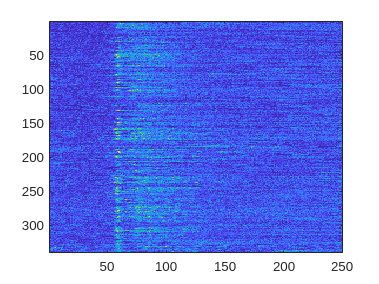


image(xx', 'CDataMapping','scaled')

If, in addition to the cells, we also take the average across time, we  are left with a single value per trial representing the per-trial  population activity averaged over time. Compare the population activity  average over time between all neurons and Visual Cortex neurons. Is the  Visual Cortex more active or less active compared to all areas together?

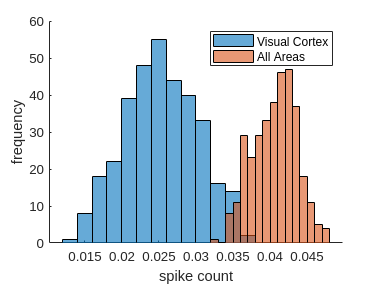

vis_cortex_mask = find(brain_areas=="visual cortex");
visual_cortex_population_activity = mean(spike_counts(:,:,vis_cortex_mask), [1,3]);
total_population_activity = mean(spike_counts, [1,3]);
clf
hold on
histogram(visual_cortex_population_activity, "DisplayName","Visual Cortex")
histogram(total_population_activity, "DisplayName","All Areas")
hold off

legend
xlabel('spike count')
ylabel('frequency')

Visual Cortex has a higher or lower activity compared to all areas together, then there must be some other areas that is compensating for  that. Which area is that?

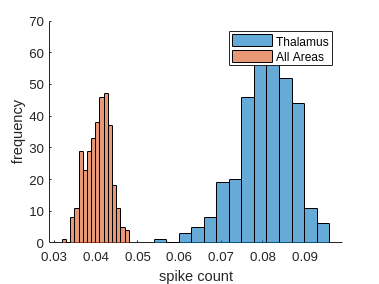

region_mask = find(brain_areas=="thalamus");
region_population_activity = mean(spike_counts(:,:,region_mask), [1,3]);
total_population_activity = mean(spike_counts, [1,3]);
clf
hold on
histogram(region_population_activity, "DisplayName","Thalamus")
histogram(total_population_activity, "DisplayName","All Areas")
hold off

legend
xlabel('spike count')
ylabel('frequency')

## Spike Count Analysis with Trial-level Categorical Variables

As we have seen before, in addition to brain area, we also have access to  several categorical variables such as response type and stimulus  contrast level. Let's see whether the pattern of neural activity would  change for different values of these categorical variables.

Let's start by turning the spike counts into firing rates. **Hint:** we need the size of the time bin for this.

dt = 0.01;
firing_rate = spike_counts/dt;

**Example:** Plot the mean firing rate (averaged across neurons and trials) over time, taking all neurons (no area specification).

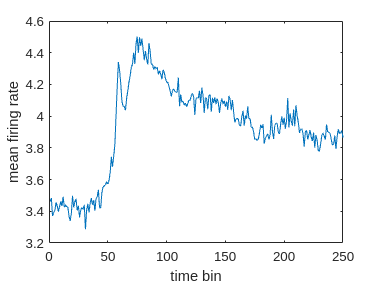

plot(mean(firing_rate, [2,3]))
xlabel('time bin')
ylabel('mean firing rate')

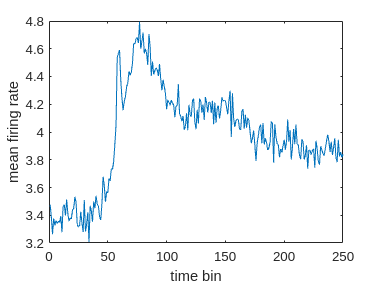

response_types = ncread("data/steinmetz_2017-12-05_Lederberg.nc","response_type") ;
response_mask = find(response_types==-1);

plot(mean(firing_rate(:,response_mask,:),[2,3]))

xlabel('time bin')
ylabel('mean firing rate')

Add to the previous plot the other two response types: one line for each  response type. Did the population activity of Visual Cortex change  noticable between the response types?

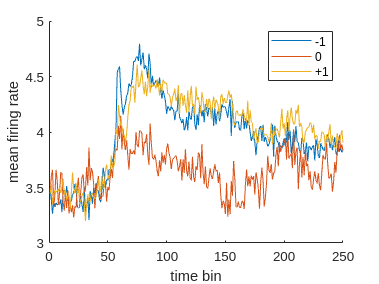

clf 
hold on
plot(mean(firing_rate(:,find(response_types==-1),:),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,find(response_types==0),:),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,find(response_types==1),:),[2,3]), "DisplayName","+1")
hold off
xlabel('time bin')
ylabel('mean firing rate')
legend

Plot the same thing as in the previous exercise, but only for neurons in the Visual Cortex.

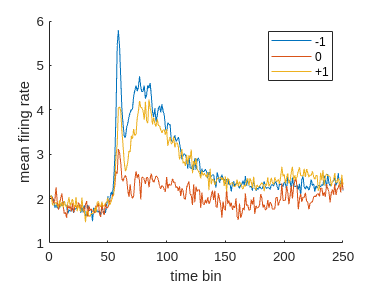

clf 
hold on
plot(mean(firing_rate(:,find(response_types==-1),vis_cortex_mask),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,find(response_types==0),vis_cortex_mask),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,find(response_types==1),vis_cortex_mask),[2,3]), "DisplayName","+1")
hold off
xlabel('time bin')
ylabel('mean firing rate')
legend

Using subplots, create four plots in a single figure, each plotting  showing the the analysis in the previous exercise for a different brain  area. Specify the brain area in the title.

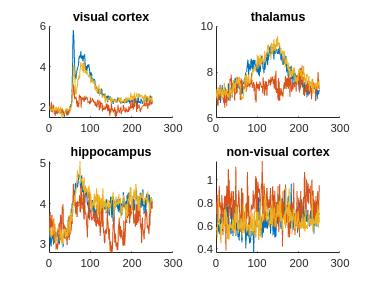

clf
subplot(2,2,1)
region = "visual cortex";
region_mask = find(brain_areas==region);
hold on
plot(mean(firing_rate(:,find(response_types==-1),region_mask),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,find(response_types==0),region_mask),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,find(response_types==1),region_mask),[2,3]), "DisplayName","+1")
title(region)
hold off

subplot(2,2,2)
region = "thalamus";
region_mask = find(brain_areas==region);
hold on
plot(mean(firing_rate(:,find(response_types==-1),region_mask),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,find(response_types==0),region_mask),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,find(response_types==1),region_mask),[2,3]), "DisplayName","+1")
title(region)
hold off

subplot(2,2,3)
region = "hippocampus";
region_mask = find(brain_areas==region);
hold on
plot(mean(firing_rate(:,find(response_types==-1),region_mask),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,find(response_types==0),region_mask),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,find(response_types==1),region_mask),[2,3]), "DisplayName","+1")
title(region)
hold off

subplot(2,2,4)
region = "non-visual cortex";
region_mask = find(brain_areas==region);
hold on
plot(mean(firing_rate(:,find(response_types==-1),region_mask),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,find(response_types==0),region_mask),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,find(response_types==1),region_mask),[2,3]), "DisplayName","+1")
title(region)
hold off